# Code Density Test

**码密度法测转移曲线是基于统计学的测量方法**，根据输入信号的概率密度函数（probability density function，pdf），统计记录输出信号的pdf，从而得到ADC的转移曲线，需要注意的是，码密度法无法体现ADC系统的非单调性，因此还需要SINAD、THD等动态测量方法。

由于难以产生高精度的阶梯信号，因此正弦信号被广泛用于码密度法测量中，而正弦信号并非均匀分布，即pdf并非一条直线，在信号值为0处概率最小，在信号值为MAX/MIN处概率最大，其分布为浴盆分布，bathtub distribution，所以在选择数据长度是需要额外注意。

基于正弦信号的码密度法测量需要解决的几个核心问题在于：

- 正弦信号的频率fin；

- INL、DNL的精度；

- 采样点数；

## bathtub distribution

对于输入正弦信号，其中共模电压不会影响Vin的分布；


$$V_{\mathrm{in}} \left(t\right)=\mathrm{Asin}\left(2\pi f_{\mathrm{in}} t\;\right)$$


其关于Vin的分布满足：


$$p\left(V\right)=\frac{1}{\pi \;}\times \frac{1}{\sqrt{\left(A^{2\;} -V^2 \right)}\;}\to \int_{-A}^A p\left(V\right)\mathrm{dV}=\frac{1}{\pi \;}\int_{-A}^A \frac{1}{\sqrt{\left(A^{2\;} -V^2 \right)}\;}\mathrm{dV}=1$$


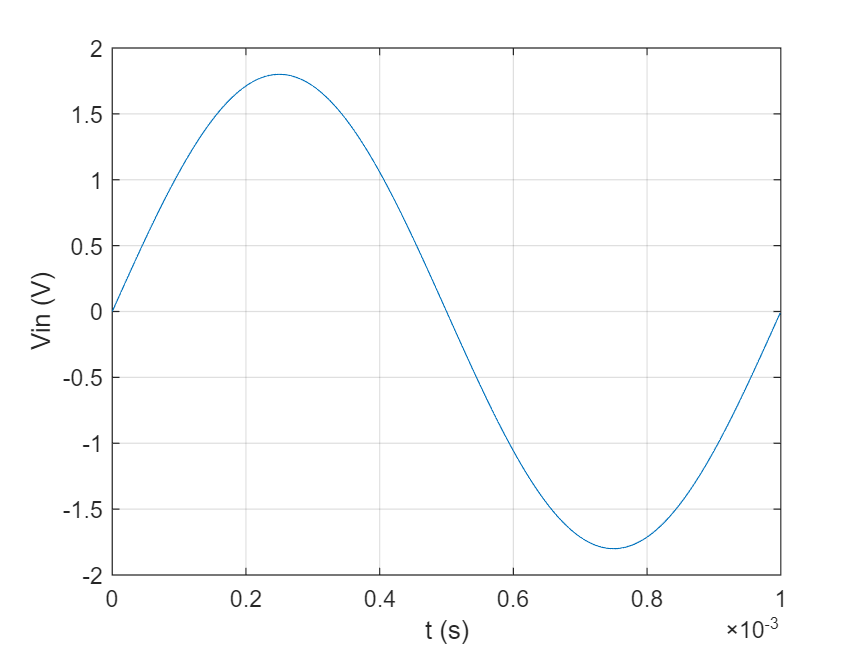

fin = 1E3;
A = 1.8;
fs = 1E6;
delta_t = 1/fs;
t = 0:delta_t:(1/fin)-delta_t;

Vin = A*sin(2*pi*fin*t);
figure
plot(t, Vin);
grid on
xlabel("t (s)");
ylabel("Vin (V)");


% pdf calculation
pdf_Vin = 1./(pi*sqrt(A^2-Vin.^2));

figure
h = histogram(repmat(Vin, [1,20]),150, 'Normalization', 'pdf')

h =   Histogram - 属性:

             Data: [0 0.0113 0.0226 0.0339 0.0452 0.0565 0.0678 0.0791 0.0904 0.1017 0.1130 0.1243 0.1356 0.1469 0.1581 0.1694 0.1807 0.1919 0.2031 0.2144 0.2256 0.2368 0.2480 0.2592 0.2704 0.2816 0.2927 0.3039 0.3150 0.3262 0.3373 0.3484 0.3595 … ]
           Values: [2.2083 0.8333 0.7500 0.5833 0.5000 0.5000 0.4167 0.4167 0.3333 0.4167 0.3333 0.3333 0.3333 0.2500 0.3333 0.2500 0.3333 0.2500 0.2500 0.2500 0.3333 0.2500 0.2500 0.1667 0.2500 0.2500 0.2500 0.2500 0.1667 0.2500 0.2500 0.1667 0.2500 … ]
          NumBins: 150
         BinEdges: [-1.8000 -1.7760 -1.7520 -1.7280 -1.7040 -1.6800 -1.6560 -1.6320 -1.6080 -1.5840 -1.5600 -1.5360 -1.5120 -1.4880 -1.4640 -1.4400 -1.4160 -1.3920 -1.3680 -1.3440 -1.3200 -1.2960 -1.2720 -1.2480 -1.2240 -1.2000 -1.1760 -1.1520 … ]
         BinWidth: 0.0240
        BinLimits: [-1.8000 1.8000]
    Normalization: 'pdf'
        FaceColo

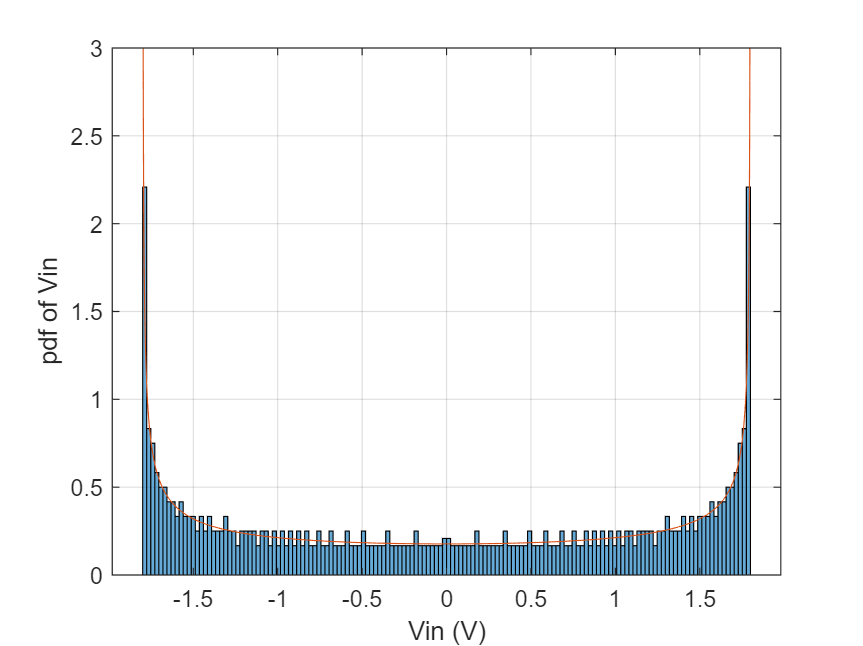

hold on;
plot(Vin, pdf_Vin)
ylim([0 3])
xlabel('Vin (V)');
ylabel("pdf of Vin");
grid on;
hold off;